# Suplementary Figure 4: zoom in the small bump amplitude regim and Bump profile for different regims  

## Fig A: Zoom in the bistable region of the figure 5 panel C

DIfferent symbols indicate the different weight matrix and different colors indicates different inital conidtion: black indicates the small bump initial condition and red the large bump condition. 

Export setup: 10.5-7

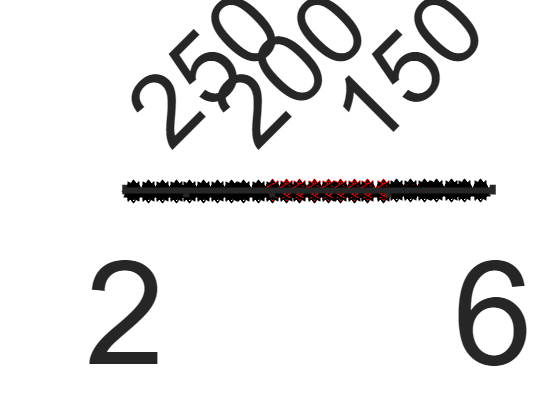

clear; clc;

% P, D, and s
P = 0.3; D = 0.3; s = 0.1;

% search weights matrix file on the directory
file_dir = fullfile(read_output_dir(), "Fig4");
if ~exist(file_dir, 'dir')
   error("Directory is not exit!")
end
list_files = look_files_by_pattern(file_dir, "amp");
list_file = list_files(contains(list_files, strrep(string(s), ".", "dot")));
file = list_file([1]);

symbs= ["o", "*", "x", "^", "square", "+", "diamond", "pentagram", ">", "<"];

fig_size = 80;
figure
t = tiledlayout(1,1);
ax1 = axes(t);
hold on

load(fullfile(file_dir, file))
n_seed = size(amplitude_T, 1)/2;

for i = 1:n_seed
    plot(ax1, w1s, amplitude_T(i, :), "r" + symbs(i), "LineWidth", 1.25, "MarkerSize", 10)
    plot(ax1, w1s, amplitude_T(i+n_seed, :), "k" + symbs(i), "LineWidth", 1.25, "MarkerSize", 10)
end


file = list_file([2]);
load(fullfile(file_dir, file))
plot(ax1, w1s, mean_flat, "k-", "LineWidth", 2.5)
plot(ax1, w1s, mean_bump, "k-", "LineWidth", 2.5)
hold off

[w1_crit] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
xline(w1_crit, "r--", "LineWidth", 1.5)


xlim([2, 6])
xticks([2:6])
xticklabels(["2", "", "", "", "6"])
ylim([-0.25, 3.5])
yticks(0:3)
yticklabels([0, "", "", 3])
fig_config(fig_size)

etas_axis = flip([100:50:250]);
f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;
w1s_axis = w_max * f(P, D, etas_axis, s);

ax2 = axes(t);
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
%ax2.YAxis.Visible = 'off';
ax2.XLim = [2, 6];
ax2.XTick = [0, w1s_axis];
ax2.XTickLabel = ["", etas_axis];
ax2.Color = 'none';
ax1.Box = "off";
%ax2.Box = 'off';
set(gca, 'fontsize', fig_size/1.2)
set(gca, 'LineWidth', fig_size / 20)
set(gca,'ytick',[])

#### Zoom in for the Y range 0-0.01 to show the small bump amplitude solution around the turing bifurcation.

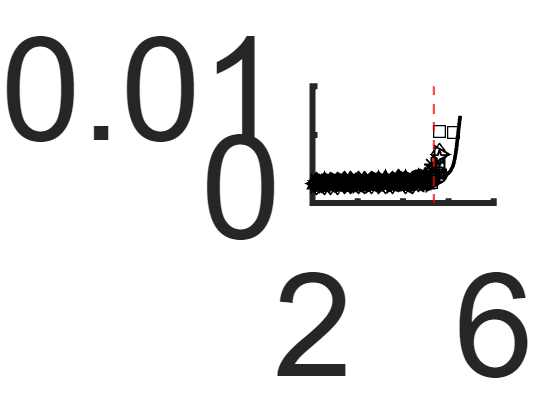

% P, D, and s
P = 0.3; D = 0.3; s = 0.1;

list_files = look_files_by_pattern(file_dir, "amp");
list_file = list_files(contains(list_files, strrep(string(s), ".", "dot")));
file = list_file([1]);
symbs= ["o", "*", "x", "^", "square", "+", "diamond", "pentagram", ">", "<"];
fig_size = 80;

figure
hold on

load(fullfile(file_dir, file))
n_seed = size(amplitude_T, 1)/2;

for i = 1:n_seed
    plot(w1s, amplitude_T(i, :), "r" + symbs(i), "LineWidth", 1.25, "MarkerSize", 10)
    plot(w1s, amplitude_T(i+n_seed, :), "k" + symbs(i), "LineWidth", 1.25, "MarkerSize", 10)
end


file = list_file([2]);
load(fullfile(file_dir, file))
plot( w1s, mean_flat, "k-", "LineWidth", 2.5)
plot(w1s, mean_bump, "k-", "LineWidth", 2.5)
hold off

[w1_crit] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
xline(w1_crit, "r--", "LineWidth", 1.5)

xlim([2, 6])
xticks([2:6])
xticklabels(["2", "", "", "", "6"])
ylim([-0.02, 0.1])
yticks([0:0.05:0.1])
yticklabels([0, "", 0.01])
fig_config(fig_size)
box off

Large bump and small bump firing rate profile in two different regims.

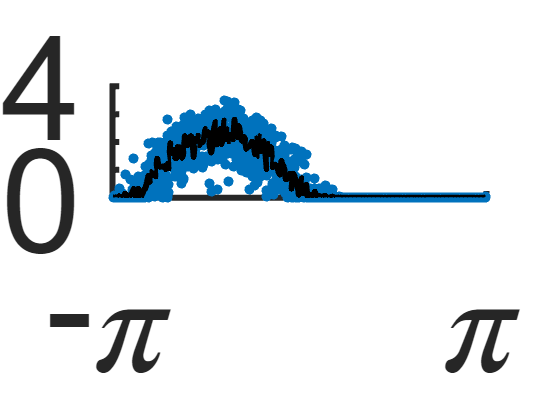

clear;clc;
large_bump_file = fullfile(read_output_dir(), "SupFig4\upper_FR.mat");
small_bump_file = fullfile(read_output_dir(), "SupFig4\lower_FR.mat");

y_max = 4;
display_FR(large_bump_file, y_max)

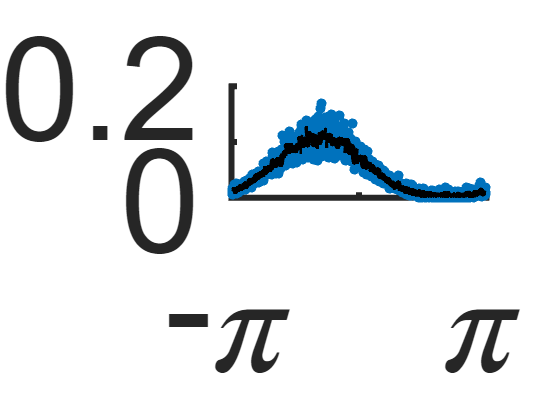


y_max = 0.2;
display_FR(small_bump_file, y_max)
ylim([0, y_max])
yticks([0:0.1:y_max])
ticklabels = [0, "", y_max];
yticklabels(ticklabels)

# Fig B : phase diagram of $w_1$ vs $w_0$, $I_0$, $\delta w$.

Similar to Fig 4F, we create three different phase diagrams for the standard ring model to study the effect of the parameters to the firing rate dynamics. 

For the ring model, the dynamic is 

$\tau \frac{d}{dt}r(x,t) = -r(x, t) + \phi\left(<W(x-\cdot), r(\cdot, t)>+I_0\right), \quad <W(x-\cdot), r(\cdot, t)> = \frac{1}{2\pi}\int_{-\pi}^{\pi}dx^\prime W(x-x^\prime)r(x^\prime, t), \quad x \in [-\pi, \pi]$,

where $W(y) = w_0+w_1\cos(y)+\delta w\cdot z(y)$, $z$ is white noise and $\delta w$ modulate the variance of random process.

For phase diagram $w_0$ vs $w_1$, we fix the $I_0= 0.2$ and $\delta w= 0$, then vary the $w_0$ from -1 to 0.75.

For phase diagram $I_0$ vs $w_1$, we fix the $w_0 = -0.25$ and $\delta w = 0$, then vary the $I_0$ form -0.5 to 0.5. 

For phase diagram $\delta w$ vs $w_1$, we fix the $w_0 = -0.25$ and $I_0 = 0.2$, then vary the $\delta w$ from 0 to 1.

10.5-7

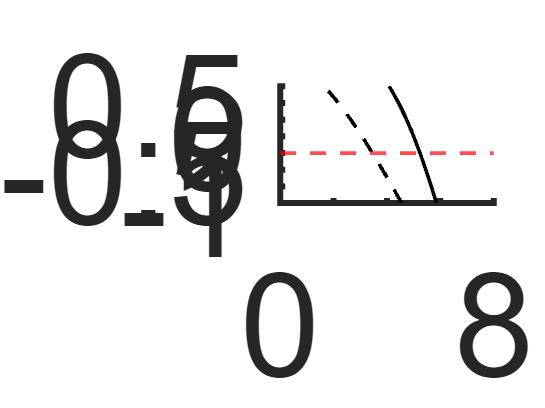

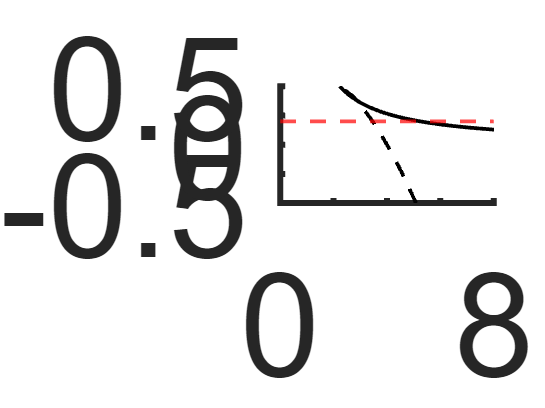

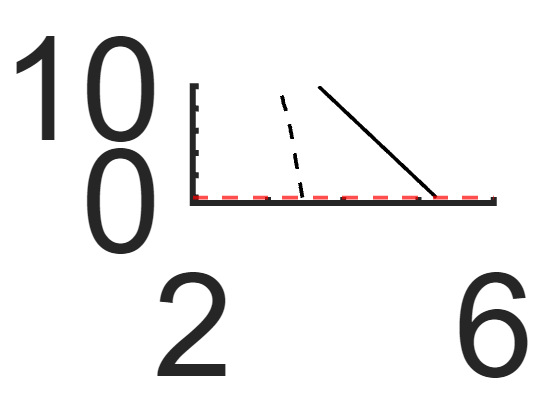

clear;clc;
load(fullfile(read_output_dir(), "SupFig4\bifurcations.mat"));

n = length(default_parameters);


for i = 1:3
    y_axis = loop_sets{i};
    saddle_x = saddle_node_bifs{i};
    turing_x = turing_bifs{i};
    
    figure
    plot(saddle_x, y_axis, "k--", "LineWidth", 2.5)
    hold on
    plot(turing_x, y_axis, "k-", "LineWidth", 2.5)
    hold off
    axis tight
    yline(default_parameters(i), "r--", "LineWidth", 2.5)
    if i == 1
        xlim([0, 8])
        ylim([-1, 0.75])
        yticks([-1:0.25:0.75])
        yticklabels([-1, "", -0.5, "", 0, "", 0.5, ""])
        xticks([0:2:8])
        xticklabels([0, "", "", "", 8])
    elseif i == 2
        xlim([0, 8])
        xticks([0:2:8])
        xticklabels([0, "", "", "", 8])
        yticks([-0.5:0.25:0.5])
        yticklabels([-0.5, "", 0, "", 0.5])
    elseif i == 3
        xlim([2, 6])
        xticks([2:6])
        xticklabels([2, "", "", "", 6])
        ylim([-0.5, 10])
        yticks([0:2:10])
        yticklabels([0, "", "", "", "", 10])
    end
    box off
    fig_config(80)
end

function list_files = look_files_by_pattern(dir_name, patterns)    
    all_files = dir(dir_name);
    list_files = {all_files.name};
    for pattern = patterns
        list_files = list_files(contains(list_files, pattern));  
    end
end
function [w1_crit, w1_crit_ring] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track)
    r0 = (1 - 2*w0*I0 - sqrt(1 - 4*w0*I0)) ./ (2*w0.^2);
    w1_crit_ring = 1 ./(w0*r0+I0);
    
    is_stack = true;
    eta = 0;
    w1_aux = 999;
    while w1_aux > w1_crit_ring
        [~, ~, ~, amp, A, ~, C] = Compute_mean_variance(P, D, eta, is_stack, M, s, nan, w0, w_max);
        w1_aux = amp + sqrt(A + C/2) * sqrt(2*pi/(n_ca3_per_track));
        
        eta = eta + 0.1;
    end

    f = @(P, D, eta, s) 2*P*D./(P+D)*(1-s^2*(P+D)).^eta;
    w1_crit = w_max * f(P, D, eta, s);
end

function display_FR(large_bump_file, y_max)
    load(large_bump_file)
    env_id = Env_track(:, end - eta);
    Selected_FR = FR_complete(env_id);
    Selected_FR_mean = grpstats(Selected_FR, phase, {'mean'});
    plot(phase, Selected_FR, ".", "MarkerSize", 20)
    hold on
    plot(unique(phase), Selected_FR_mean, "k-", "LineWidth", 4);
    hold off
    xlim([-pi, pi])
    xticks([-pi, 0, pi])
    xticklabels(["-\pi", "", "\pi"])
    ylim([0, y_max])
    
    if y_max < 1
        factor = 10;
    else
        factor = 1;
    end

    y_max_aux = y_max * factor;

    yticks([0:y_max_aux])
    ticklabels = [0, repmat("", 1, y_max_aux - 1), y_max];
    yticklabels(ticklabels)
    box off
    fig_config(80)
end